clear
clearvars
close all
clc

filePath = 'C:\Users\alisa\Downloads\feeds.csv';

data = readtable(filePath);

head(data)

             created_at              entry_id    field1    field2    field3    latitude    longitude    elevation    status
    _____________________________    ________    ______    ______    ______    ________    _________    _________    ______

    {'2026-10-20T13:39:12+00:00'}       1        21.994      57       NaN        NaN          NaN          NaN        NaN  
    {'2026-10-20T13:39:28+00:00'}       2        22.972      55       NaN        NaN          NaN          NaN        NaN  
    {'2026-10-20T13:39:43+00:00'}       3        22.483      58       NaN        NaN          NaN          NaN        NaN  
    {'2026-10-20T13:39:59+00:00'}       4        22.972      52       NaN

summary(data)


data: 705×9 table

Variables:

    created_at: cell array of character vectors
    entry_id: double
    field1: double
    field2: double
    field3: double
    latitude: double
    longitude: double
    elevation: double
    status: double

Statistics for applicable variables:

                  NumMissing        Min          Median           Max           Mean            Std     

    created_at         0                                                                                
    entry_id           0                1            353            705            353        203.6603  
    field1             0          14.0945        16.7055        39.6000        1

disp(data.Properties.VariableNames)

    {'created_at'}    {'entry_id'}    {'field1'}    {'field2'}    {'field3'}    {'latitude'}    {'longitude'}    {'elevation'}    {'status'}



Timestamp = datetime( ...
    string(data.created_at), ...
    'InputFormat','yyyy-MM-dd''T''HH:mm:ssXXX', ...
    'TimeZone','UTC');

LM35Temperature = data.field1;
DHTTemperature  = data.field2;
DHTHumidity     = data.field3;

fprintf('Original rows: %d\n', height(data));

Original rows: 705


fprintf('Missing humidity: %d\n', sum(isnan(DHTHumidity)));

Missing humidity: 44


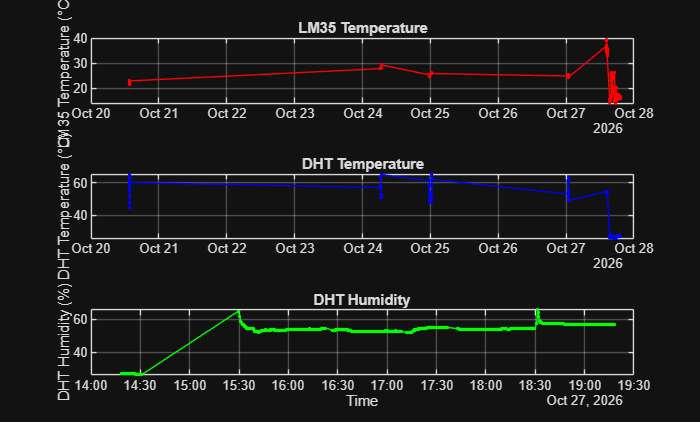

figure

tiledlayout(3,1)

nexttile
plot(Timestamp, LM35Temperature, 'r.-')
grid on
ylabel('LM35 Temperature (°C)')
title('LM35 Temperature')

nexttile
plot(Timestamp, DHTTemperature, 'b.-')
grid on
ylabel('DHT Temperature (°C)')
title('DHT Temperature')

nexttile
plot(Timestamp, DHTHumidity, 'g.-')
grid on
ylabel('DHT Humidity (%)')
xlabel('Time')
title('DHT Humidity')

validRows = ...
    isfinite(LM35Temperature) & ...
    isfinite(DHTHumidity) & ...
    LM35Temperature >= 0 & LM35Temperature <= 150 & ...
    DHTHumidity >= 0 & DHTHumidity <= 100;

cleanData = table( ...
    Timestamp(validRows), ...
    DHTHumidity(validRows), ...
    LM35Temperature(validRows), ...
    'VariableNames', ...
    {'Timestamp','DHTHumidity','LM35Temperature'});

fprintf('Clean rows: %d\n', height(cleanData));

Clean rows: 661



head(cleanData)

         Timestamp          DHTHumidity    LM35Temperature
    ____________________    ___________    _______________

    27-Oct-2026 14:18:14       27.1             36.9      
    27-Oct-2026 14:18:34       27.1               37      
    27-Oct-2026 14:18:54       27.2               39      
    27-Oct-2026 14:19:14       27.2             39.5      
    27-Oct-2026 14:19:34       27.2             39.6      
    27-Oct-2026 14:20:15       27.2             36.4      
    27-Oct-2026 14:20:34       27.2             36.7      
    27-Oct-2026 14:20:54       27.2             36.4      



n = height(cleanData);
splitIndex = floor(0.80 * n);

trainData = cleanData(1:splitIndex,:);
testData  = cleanData(splitIndex+1:end,:);

fprintf('Training rows: %d\n', height(trainData));

Training rows: 528


fprintf('Testing rows: %d\n', height(testData));

Testing rows: 133


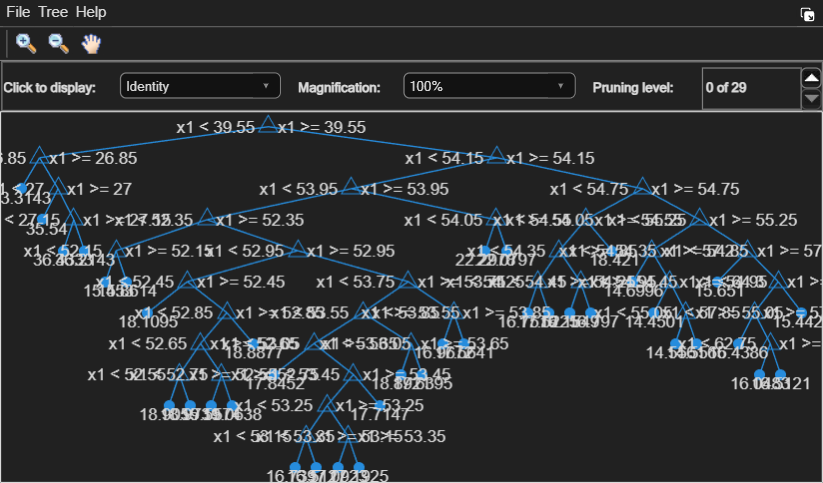

fineTreeModel = fitrtree( ...
    trainData.DHTHumidity, ...
    trainData.LM35Temperature, ...
    'MaxNumSplits',100, ...
    'MinLeafSize',1);
view(fineTreeModel, 'Mode', 'graph')

actualTemperature = testData.LM35Temperature;

predictedTemperature = predict( ...
    fineTreeModel, ...
    testData.DHTHumidity);

trainingMean = mean(trainData.LM35Temperature);

meanPrediction = repmat( ...
    trainingMean, ...
    height(testData), 1);

treeError = predictedTemperature - actualTemperature;
meanError = meanPrediction - actualTemperature;

treeRMSE = sqrt(mean(treeError.^2));
treeMAE  = mean(abs(treeError));
treeR2   = 1 - sum(treeError.^2) / ...
    sum((actualTemperature - mean(actualTemperature)).^2);

meanRMSE = sqrt(mean(meanError.^2));
meanMAE  = mean(abs(meanError));
meanR2   = 1 - sum(meanError.^2) / ...
    sum((actualTemperature - mean(actualTemperature)).^2);

metrics = table( ...
    {'Fine Tree'; 'Training Mean'}, ...
    [treeRMSE; meanRMSE], ...
    [treeMAE; meanMAE], ...
    [treeR2; meanR2], ...
    'VariableNames', {'Model','RMSE','MAE','R2'});

disp(metrics)

          Model           RMSE        MAE        R2   
    _________________    _______    _______    _______

    {'Fine Tree'    }    0.73035    0.63272    -56.202
    {'Training Mean'}     2.7625     2.7608    -817.35



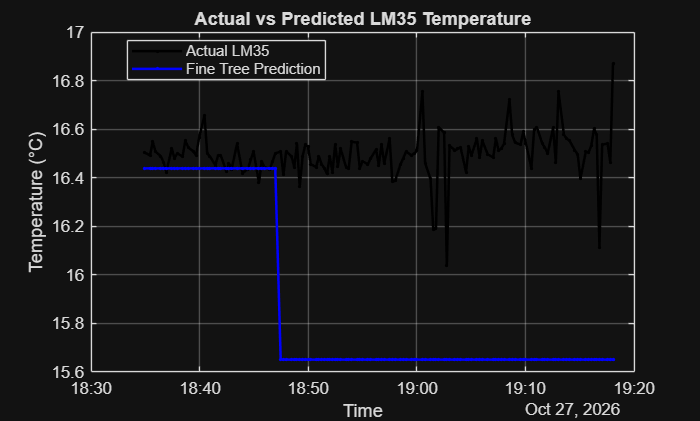

figure

plot(testData.Timestamp, actualTemperature, ...
    'k.-', 'LineWidth', 1.5)

hold on

plot(testData.Timestamp, predictedTemperature, ...
    'b.-', 'LineWidth', 1.5)

grid on
legend('Actual LM35','Fine Tree Prediction', ...
    'Location','best')

xlabel('Time')
ylabel('Temperature (°C)')
title('Actual vs Predicted LM35 Temperature')

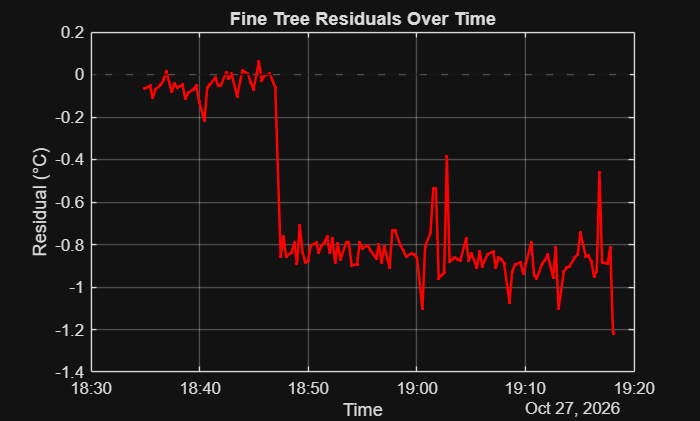

figure

plot(testData.Timestamp, treeError, ...
    'r.-', 'LineWidth', 1.5)

hold on
yline(0,'k--')

grid on
xlabel('Time')
ylabel('Residual (°C)')
title('Fine Tree Residuals Over Time')

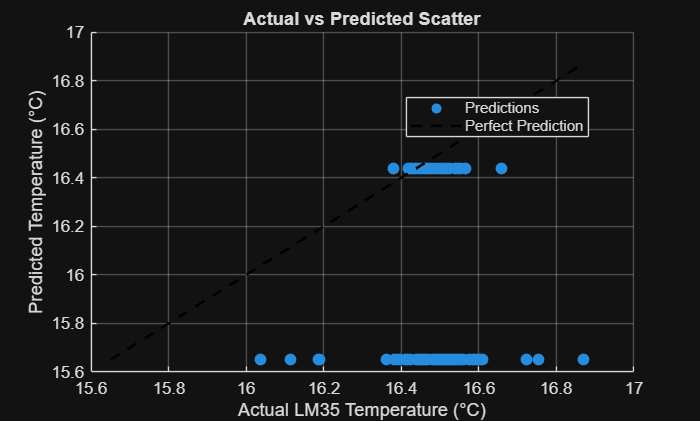

figure

scatter(actualTemperature, predictedTemperature, ...
    50, 'filled')

hold on

minimumValue = min([actualTemperature; predictedTemperature]);
maximumValue = max([actualTemperature; predictedTemperature]);

plot([minimumValue maximumValue], ...
    [minimumValue maximumValue], ...
    'k--', 'LineWidth', 1.5)

grid on
xlabel('Actual LM35 Temperature (°C)')
ylabel('Predicted Temperature (°C)')
title('Actual vs Predicted Scatter')
legend('Predictions','Perfect Prediction','Location','best')

linearModel = fitlm( ...
    trainData.DHTHumidity, ...
    trainData.LM35Temperature);

linearPrediction = predict( ...
    linearModel, ...
    testData.DHTHumidity);

linearError = linearPrediction - actualTemperature;

linearRMSE = sqrt(mean(linearError.^2));
linearMAE  = mean(abs(linearError));
linearR2   = 1 - sum(linearError.^2) / ...
    sum((actualTemperature - mean(actualTemperature)).^2);

comparison = table( ...
    {'Fine Tree'; 'Linear Regression'; 'Training Mean'}, ...
    [treeRMSE; linearRMSE; meanRMSE], ...
    [treeMAE; linearMAE; meanMAE], ...
    [treeR2; linearR2; meanR2], ...
    'VariableNames', {'Model','RMSE','MAE','R2'});

disp(comparison)

            Model             RMSE        MAE        R2   
    _____________________    _______    _______    _______

    {'Fine Tree'        }    0.73035    0.63272    -56.202
    {'Linear Regression'}    0.44032    0.42608    -19.791
    {'Training Mean'    }     2.7625     2.7608    -817.35

